# Optima Bodluv

option = "All options";
sheetName = "blue_shot_costs";
data = importData(sheetName, option);

data.BlueEffector = replace(string(data.BlueEffector), "_", "-");

% data(data.BlueEffector == "BLUE-EF03CANNON" & data.RedTarget == "RED_PGMStandOff(GBU-39)System" & data.Outcome == "kill" & data.Scenario == "Regio", :)

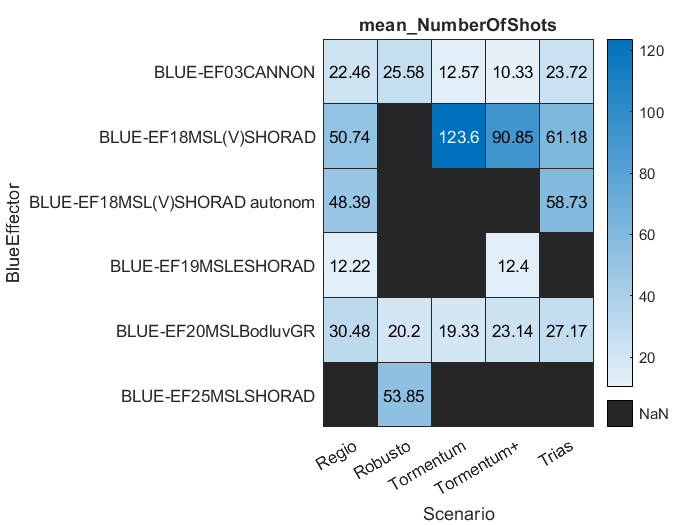

grpVar = ["Scenario"; "BlueEffector"];
dataVar = "NumberOfShots";

statarray = rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "BlueEffector"]);
statarray = rowfun(@mean, statarray, 'InputVariables', "Var5", 'GroupingVariables', ["Scenario"; "BlueEffector"]);
statarray.Properties.VariableNames{end} = ['mean_', char(dataVar)];
figure("Name", "BlueNumberOfShots")
heatmap(statarray, grpVar{1}, grpVar{2}, 'ColorVariable', "mean_"+dataVar, "ColorMethod", "none");


saveResults("data")